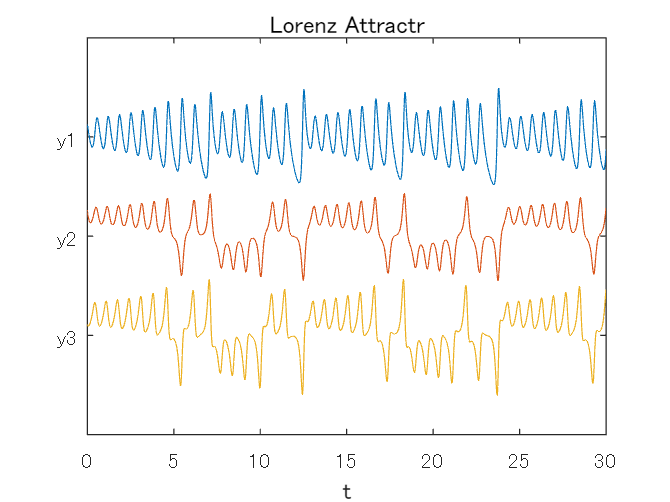

sigma = 10;
beta = 8/3;
rho = 28;
eta = sqrt(beta*(rho-1));
A = [ -beta 0 eta;
    0 -sigma sigma;
    -eta rho -1 ];
v0 = [rho-1 eta eta]';
y0 = v0 + [3 2 -4]';
tspan = [0 30];

[t,y] = ode45(@(t,y) lorenzeqn(t,y,A), tspan, y0);

plot(t,[y(:,1)+15 y(:,2) y(:,3)-40]);
axis([0 30 -80 80])
set(gca,'ytick',[-40 0 40],'yticklabel',{'y3','y2','y1'})
xlabel('t')
title('Lorenz Attractr')

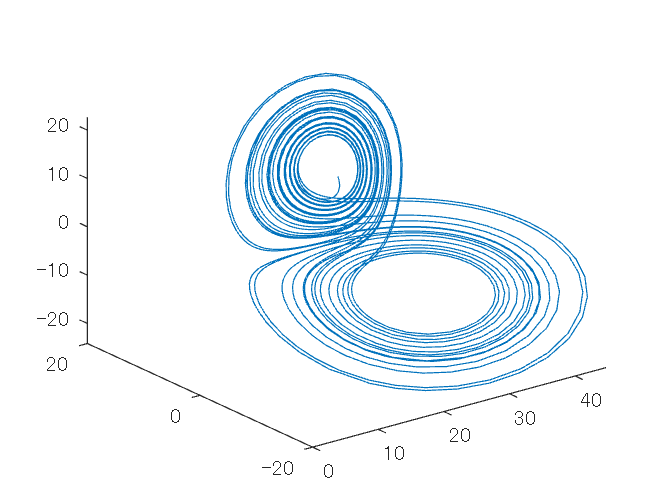


plot3(y(:,1),y(:,2),y(:,3))

function ydot = lorenzeqn(t,y,A)

A(1,3) = y(2);
A(3,1) = -y(2);
ydot = A*y;

end